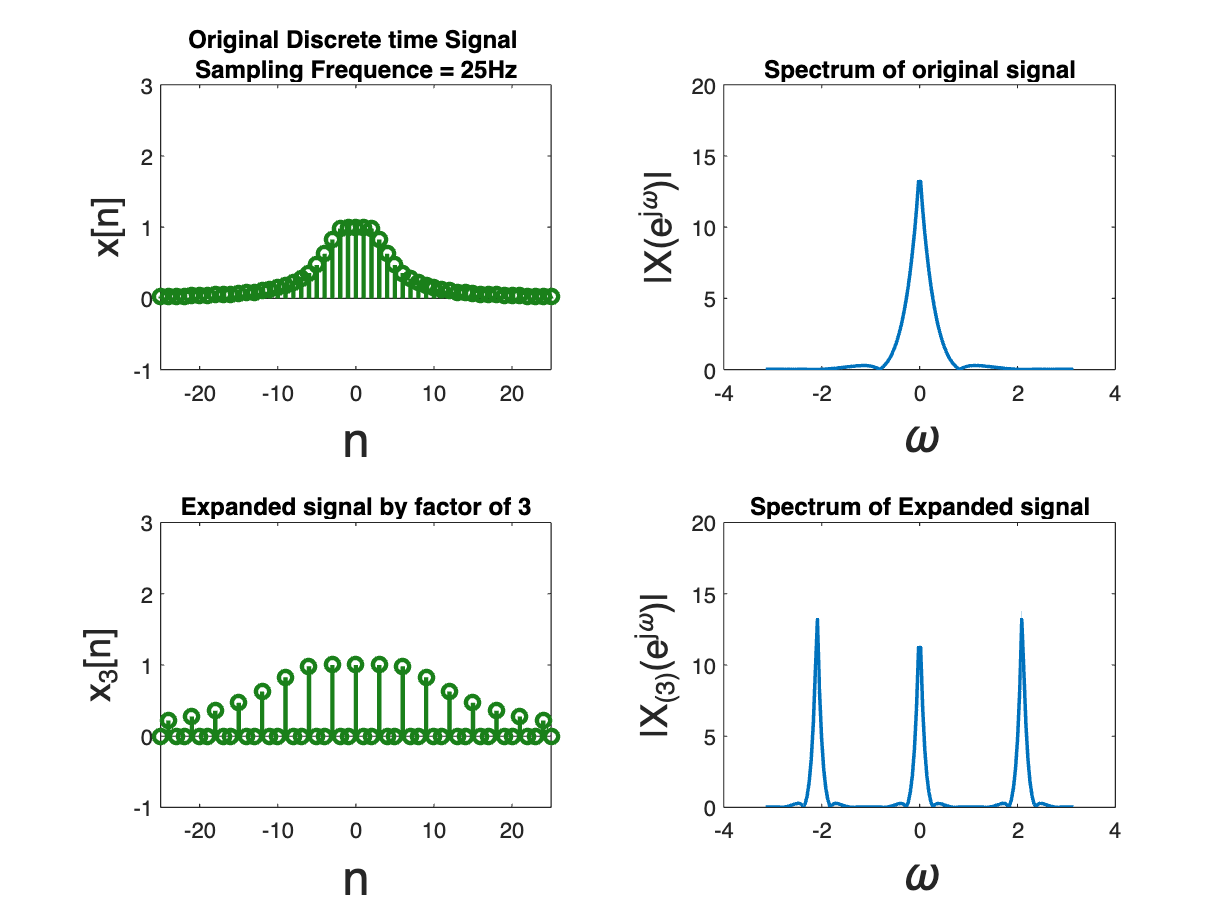

freq_sampling = 25;
time_sampling = 2*pi/freq_sampling;
samples = 100;
% sampling taken from f(x) continuous time signal defined at last.
x_sampled = [];
for i=-samples:1:samples
    x_sampled(end+1)=f(i*time_sampling);
end

tiledlayout(2,2)
nexttile
% stem plot of samples taken from original function
stem((-samples:samples),x_sampled,LineWidth=2,Color=[0.1,0.5,0.1])
title("Original Discrete time Signal "+newline+"Sampling Frequence = "+freq_sampling+"Hz")
xlabel("n","FontSize",22)
ylabel("x[n]","FontSize",17)
xlim([-25,25])
ylim([-1,3])

% performing DFT on sample
[w1, res1]=DFT(x_sampled,150);
nexttile
%frequency spectrum of above sample
plot(w1,abs(res1),LineWidth=1.6)
title("Spectrum of original signal")
xlim([-4,4])
ylim([0,20])
xlabel("\omega","FontSize",22)
ylabel("|X(e^{j\omega})|","FontSize",17)


% Discrete time expansion of above sample
expansion_factor=3;
x_new = discrete_time_expansion(x_sampled,expansion_factor);
nexttile
stem((-samples*expansion_factor:samples*expansion_factor),x_new,LineWidth=2,Color=[0.1,0.5,0.1])
title("Expanded signal by factor of "+expansion_factor)
xlabel("n","FontSize",22)
ylabel("x_{"+expansion_factor+"}[n]","FontSize",17)
xlim([-25,25])
ylim([-1,3])

% DFT of expanded signal  (sample)
[w2, res2]=DFT(x_new,150);
nexttile
plot(w2,abs(res2),LineWidth=1.6)
title("Spectrum of Expanded signal")
xlabel("\omega","FontSize",22)
ylabel("|X_{("+expansion_factor+")}(e^{j\omega})|","FontSize",17)
xlim([-4,4])
ylim([0,20])

function [w,out] = DFT(signal,freq_samples)
    w=linspace(-pi,pi,freq_samples);
    temp=zeros([1,freq_samples]);
    for k =(1:length(signal))
        temp=temp+(signal(k)*exp(-1i*k*w));
    end
    out=temp;
end

function sample_out = discrete_time_expansion(sample_in,expansion_factor)
    temp = [];
    size=length(sample_in);
    for k=(1:size)
        temp(end+1)=sample_in(k);
        if k<size
            for l=(1:expansion_factor-1)
                temp(end+1)=0;
            end
        end
    end
    sample_out=temp;
    
end

function out = f(x)
    if abs(x)<0.1
        out =1;
    else
        out = 1-exp(-1/(x^2));
    end
end
